# staticな学習データをGPR

テストデータとも比較して，精度も確認する．

シンプルに解いて，オイラーの回転運動方程式を解いてlight curveを計算して，比較する．

csvの中身：

- xTrain: [q, satPos, obsPos, sunPos]

- yTrain: [mApp]

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(strcat(curdir, '/../../gpryui/'));

tStart = tic;

### input values directly

% inputGP = "attitude"
% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean" % [q, r, obsECI, mApp_past]
inputGP = "attitude, relativePosition, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"


predictionStep = 1; % 1:ode, 2: simpleGP as a prediction model
validData = "boxWing_lcAtti_onOrbit.mat"

validData = "boxWing_lcAtti_onOrbit.mat"


tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
% tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

tSpanPast = 20;

### read data

% read train data ------
datadir = strcat(curdir, '/../../data/static/');
cddir = datadir;
cd(cddir)
trainStruct = dir('*.csv');
trainDF = [];
for i = 1:1:size(trainStruct, 1)
    fName = trainStruct(i).name;
    df = readmatrix(fName); % [t_jd, mApp, q, r, obsECI, sunPosI, mApp_pastMean], nIniCon x 16
    trainDF = [trainDF; df];
end
cd(curdir)

% read valid data -----
valid = load(validData); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

### data handling

% train data ------

outputDim = 1; % [mApp]
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    % inputDim = 11; % [q, r, obsECI, mApp_pastMean], nx11, sunPosI はほぼ動いてないとして入力に入れない
    x_train = trainDF(:,3:end);

    % 入力のorderを揃えたい
    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    % x_train_r = x_train_r ./ max(x_train_r, [], "all");
    % x_train_obsECI = x_train_obsECI ./ max(x_train_obsECI, [], "all");
    r_valid_max = max(valid.r, [], "all");
    obsECI_valid_max = max(valid.obsECI, [], "all");
    x_train_r = x_train_r ./ r_valid_max;
    x_train_obsECI = x_train_obsECI ./ obsECI_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_r, x_train_obsECI, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_train = trainDF(:,3:end);

    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_obsToTarget = x_train_r - x_train_obsECI;
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    obsToTarget_valid_max = max(valid.r - valid.obsECI, [], "all"); % 相対位置の最大値を取得 for order調整
    x_train_obsToTarget = x_train_obsToTarget ./ obsToTarget_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_obsToTarget, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, mApp_pastMean")
    % inputDim = 5; % [q, mApp_pastMean]
    x_train = [trainDF(:,3:6), trainDF(:,end)]; % [q, mApp_pastMean]
    inputDim = size(x_train, 2);
elseif strcmp(inputGP, "attitude")
    x_train = trainDF(:,3:6); % [q]
    inputDim = size(x_train, 2);
end
y_train = trainDF(:, 2); % [mApp]

size(x_train)

ans =         3852           8


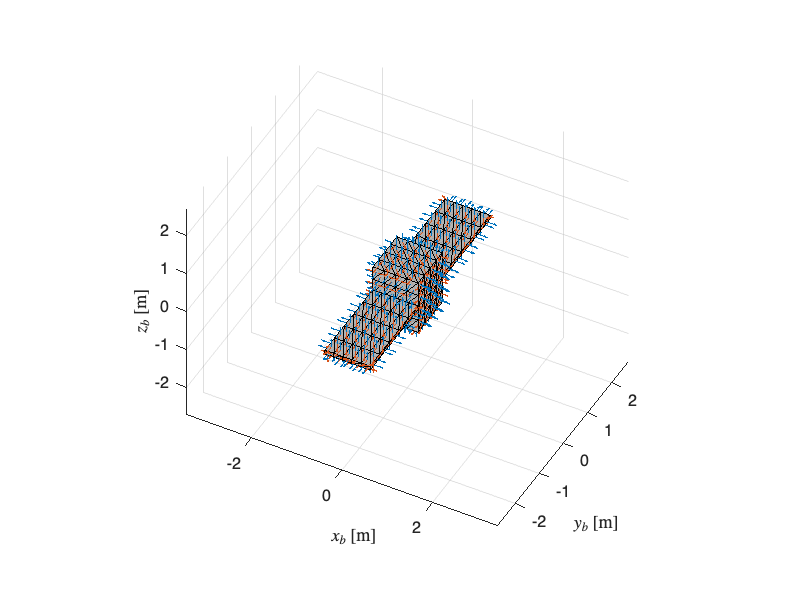


% light curve の inf を処理
y_train(isinf(y_train)) = NaN;
y_train = fillmissing(y_train, 'previous'); % mAppのinfを直前の値に置換
x_train(isinf(x_train)) = NaN;
x_train = fillmissing(x_train, 'previous'); % mApp_pastMeanの inf 処理
valid.mApp(isinf(valid.mApp)) = NaN;
valid.mApp = fillmissing(valid.mApp, 'previous'); % 真値のmAppも処理

% train data の各スカラー出力の平均を0にする for GPR
y_train_mean = mean(y_train); % [1, 1]
y_train = y_train - y_train_mean; % [:, 1], broadcasting


% valid data
t_ = valid.t_;
sat = valid.sat;
showSC(sat, "Normal", "on") % visualize satellite

### create a GP model (x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do) as a .mat file

tStartLearning = tic;
% [K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]
K_Dp = 0; Kinv_Dp = 0; % 時間短縮のために一旦0で．．

[K_Do, Kinv_Do] = kernelMatrix(x_train(:,1:inputDim), params); % 
tEndLearning = toc(tStartLearning) / 60;
strcat("calculation time for learning [min] : ", num2str(tEndLearning))

ans = "calculation time for learning [min] : 0.10193"

fName = 'constGP';
save(strcat(fName, '.mat'), 'x_train', 'y_train', 'y_train_mean', 'K_Dp', 'Kinv_Dp', 'K_Do', 'Kinv_Do', 'params', '-v7.3');

## 逐次的に回帰を行い，回帰モデルの精度を確認

### conditions for ode

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

tle = readTLE('JCSAT2_edited.txt', const);
jd = tle.jd;

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

rIni = valid.r(1,:);
vIni = valid.v(1,:);
qIni = valid.q(1,:);
wIni = valid.w(1,:);

xIni = [rIni, vIni, qIni, wIni];

obsECIIni = valid.obsECI(1,:);
sunPosIIni = valid.sunPosI(1,:);
mApp_pastMeanIni = valid.mApp(1,1);

obsToTargetIni = rIni - obsECIIni;

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

### ode と gpr を回して逐次的に回帰

% preallocation
x_reg = zeros(size(t_, 1), inputDim); % preallocation [q, satPos, obsPos, sunPos]. inputs for regression
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    x_reg(1,:) = [qIni, rIni./r_valid_max, obsECIIni./obsECI_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_reg(1,:) = [qIni, obsToTargetIni./obsToTarget_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    x_reg = [qIni, mApp_pastMeanIni];
elseif strcmp(inputGP, "attitude")
    x_reg = [qIni];
end

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_,1), outputDim); % [mApp]
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu));

for i = 1:1:size(t_, 1)-1

the number of the time step i: 1 


the calculation time to go forward to the next step: 0.002058 [min]


the number of the time step i: 2 


the calculation time to go forward to the next step: 0.000229 [min]


the number of the time step i: 3 


the calculation time to go forward to the next step: 0.000188 [min]


the number of the time step i: 4 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 5 


the calculation time to go forward to the next step: 0.000448 [min]


the number of the time step i: 6 


the calculation time to go forward to the next step: 0.000419 [min]


the number of the time step i: 7 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 8 


the calculation time to go forward to the next step: 0.000268 [min]


the number of the time step i: 9 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 10 


the calculation time to go forward to the next step: 0.000609 [min]


the number of the time step i: 11 


the calculation time to go forward to the next step: 0.000564 [min]


the number of the time step i: 12 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 13 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 14 


the calculation time to go forward to the next step: 0.000177 [min]


the number of the time step i: 15 


the calculation time to go forward to the next step: 0.000465 [min]


the number of the time step i: 16 


the calculation time to go forward to the next step: 0.000229 [min]


the number of the time step i: 17 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 18 


the calculation time to go forward to the next step: 0.000680 [min]


the number of the time step i: 19 


the calculation time to go forward to the next step: 0.000806 [min]


the number of the time step i: 20 


the calculation time to go forward to the next step: 0.000661 [min]


the number of the time step i: 21 


the calculation time to go forward to the next step: 0.000430 [min]


the number of the time step i: 22 


the calculation time to go forward to the next step: 0.000702 [min]


the number of the time step i: 23 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 24 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 25 


the calculation time to go forward to the next step: 0.000199 [min]


the number of the time step i: 26 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 27 


the calculation time to go forward to the next step: 0.000154 [min]


the number of the time step i: 28 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 29 


the calculation time to go forward to the next step: 0.000365 [min]


the number of the time step i: 30 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 31 


the calculation time to go forward to the next step: 0.000145 [min]


the number of the time step i: 32 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 33 


the calculation time to go forward to the next step: 0.000193 [min]


the number of the time step i: 34 


the calculation time to go forward to the next step: 0.000187 [min]


the number of the time step i: 35 


the calculation time to go forward to the next step: 0.000513 [min]


the number of the time step i: 36 


the calculation time to go forward to the next step: 0.000188 [min]


the number of the time step i: 37 


the calculation time to go forward to the next step: 0.000214 [min]


the number of the time step i: 38 


the calculation time to go forward to the next step: 0.000342 [min]


the number of the time step i: 39 


the calculation time to go forward to the next step: 0.000221 [min]


the number of the time step i: 40 


the calculation time to go forward to the next step: 0.000246 [min]


the number of the time step i: 41 


the calculation time to go forward to the next step: 0.000150 [min]


the number of the time step i: 42 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 43 


the calculation time to go forward to the next step: 0.000236 [min]


the number of the time step i: 44 


the calculation time to go forward to the next step: 0.000217 [min]


the number of the time step i: 45 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 46 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 47 


the calculation time to go forward to the next step: 0.000195 [min]


the number of the time step i: 48 


the calculation time to go forward to the next step: 0.000202 [min]


the number of the time step i: 49 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 50 


the calculation time to go forward to the next step: 0.000302 [min]


the number of the time step i: 51 


the calculation time to go forward to the next step: 0.000542 [min]


the number of the time step i: 52 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 53 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 54 


the calculation time to go forward to the next step: 0.000169 [min]


the number of the time step i: 55 


the calculation time to go forward to the next step: 0.000190 [min]


the number of the time step i: 56 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 57 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 58 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 59 


the calculation time to go forward to the next step: 0.000187 [min]


the number of the time step i: 60 


the calculation time to go forward to the next step: 0.000288 [min]


the number of the time step i: 61 


the calculation time to go forward to the next step: 0.000145 [min]


the number of the time step i: 62 


the calculation time to go forward to the next step: 0.000135 [min]


the number of the time step i: 63 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 64 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 65 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 66 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 67 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 68 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 69 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 70 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 71 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 72 


the calculation time to go forward to the next step: 0.000150 [min]


the number of the time step i: 73 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 74 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 75 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 76 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 77 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 78 


the calculation time to go forward to the next step: 0.000333 [min]


the number of the time step i: 79 


the calculation time to go forward to the next step: 0.000352 [min]


the number of the time step i: 80 


the calculation time to go forward to the next step: 0.000190 [min]


the number of the time step i: 81 


the calculation time to go forward to the next step: 0.000516 [min]


the number of the time step i: 82 


the calculation time to go forward to the next step: 0.000666 [min]


the number of the time step i: 83 


the calculation time to go forward to the next step: 0.000813 [min]


the number of the time step i: 84 


the calculation time to go forward to the next step: 0.000258 [min]


the number of the time step i: 85 


the calculation time to go forward to the next step: 0.000185 [min]


the number of the time step i: 86 


the calculation time to go forward to the next step: 0.000271 [min]


the number of the time step i: 87 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 88 


the calculation time to go forward to the next step: 0.000191 [min]


the number of the time step i: 89 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 90 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 91 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 92 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 93 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 94 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 95 


the calculation time to go forward to the next step: 0.000345 [min]


the number of the time step i: 96 


the calculation time to go forward to the next step: 0.000182 [min]


the number of the time step i: 97 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 98 


the calculation time to go forward to the next step: 0.000135 [min]


the number of the time step i: 99 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 100 


the calculation time to go forward to the next step: 0.000209 [min]


the number of the time step i: 101 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 102 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 103 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 104 


the calculation time to go forward to the next step: 0.000183 [min]


the number of the time step i: 105 


the calculation time to go forward to the next step: 0.000188 [min]


the number of the time step i: 106 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 107 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 108 


the calculation time to go forward to the next step: 0.000193 [min]


the number of the time step i: 109 


the calculation time to go forward to the next step: 0.000191 [min]


the number of the time step i: 110 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 111 


the calculation time to go forward to the next step: 0.000211 [min]


the number of the time step i: 112 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 113 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 114 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 115 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 116 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 117 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 118 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 119 


the calculation time to go forward to the next step: 0.000236 [min]


the number of the time step i: 120 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 121 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 122 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 123 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 124 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 125 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 126 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 127 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 128 


the calculation time to go forward to the next step: 0.000187 [min]


the number of the time step i: 129 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 130 


the calculation time to go forward to the next step: 0.000212 [min]


the number of the time step i: 131 


the calculation time to go forward to the next step: 0.000198 [min]


the number of the time step i: 132 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 133 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 134 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 135 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 136 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 137 


the calculation time to go forward to the next step: 0.000143 [min]


the number of the time step i: 138 


the calculation time to go forward to the next step: 0.000192 [min]


the number of the time step i: 139 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 140 


the calculation time to go forward to the next step: 0.000124 [min]


the number of the time step i: 141 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 142 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 143 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 144 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 145 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 146 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 147 


the calculation time to go forward to the next step: 0.000289 [min]


the number of the time step i: 148 


the calculation time to go forward to the next step: 0.000144 [min]


the number of the time step i: 149 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 150 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 151 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 152 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 153 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 154 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 155 


the calculation time to go forward to the next step: 0.000237 [min]


the number of the time step i: 156 


the calculation time to go forward to the next step: 0.000207 [min]


the number of the time step i: 157 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 158 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 159 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 160 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 161 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 162 


the calculation time to go forward to the next step: 0.000181 [min]


the number of the time step i: 163 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 164 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 165 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 166 


the calculation time to go forward to the next step: 0.000185 [min]


the number of the time step i: 167 


the calculation time to go forward to the next step: 0.000150 [min]


the number of the time step i: 168 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 169 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 170 


the calculation time to go forward to the next step: 0.000182 [min]


the number of the time step i: 171 


the calculation time to go forward to the next step: 0.000279 [min]


the number of the time step i: 172 


the calculation time to go forward to the next step: 0.000127 [min]


the number of the time step i: 173 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 174 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 175 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 176 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 177 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 178 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 179 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 180 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 181 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 182 


the calculation time to go forward to the next step: 0.000257 [min]


the number of the time step i: 183 


the calculation time to go forward to the next step: 0.000185 [min]


the number of the time step i: 184 


the calculation time to go forward to the next step: 0.000294 [min]


the number of the time step i: 185 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 186 


the calculation time to go forward to the next step: 0.000173 [min]


the number of the time step i: 187 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 188 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 189 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 190 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 191 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 192 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 193 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 194 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 195 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 196 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 197 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 198 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 199 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 200 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 201 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 202 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 203 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 204 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 205 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 206 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 207 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 208 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 209 


the calculation time to go forward to the next step: 0.000186 [min]


the number of the time step i: 210 


the calculation time to go forward to the next step: 0.000173 [min]


the number of the time step i: 211 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 212 


the calculation time to go forward to the next step: 0.000125 [min]


the number of the time step i: 213 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 214 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 215 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 216 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 217 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 218 


the calculation time to go forward to the next step: 0.000154 [min]


the number of the time step i: 219 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 220 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 221 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 222 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 223 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 224 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 225 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 226 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 227 


the calculation time to go forward to the next step: 0.000205 [min]


the number of the time step i: 228 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 229 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 230 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 231 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 232 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 233 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 234 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 235 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 236 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 237 


the calculation time to go forward to the next step: 0.000239 [min]


the number of the time step i: 238 


the calculation time to go forward to the next step: 0.000383 [min]


the number of the time step i: 239 


the calculation time to go forward to the next step: 0.000331 [min]


the number of the time step i: 240 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 241 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 242 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 243 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 244 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 245 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 246 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 247 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 248 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 249 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 250 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 251 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 252 


the calculation time to go forward to the next step: 0.000205 [min]


the number of the time step i: 253 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 254 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 255 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 256 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 257 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 258 


the calculation time to go forward to the next step: 0.000192 [min]


the number of the time step i: 259 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 260 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 261 


the calculation time to go forward to the next step: 0.000145 [min]


the number of the time step i: 262 


the calculation time to go forward to the next step: 0.000127 [min]


the number of the time step i: 263 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 264 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 265 


the calculation time to go forward to the next step: 0.000342 [min]


the number of the time step i: 266 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 267 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 268 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 269 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 270 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 271 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 272 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 273 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 274 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 275 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 276 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 277 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 278 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 279 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 280 


the calculation time to go forward to the next step: 0.000183 [min]


the number of the time step i: 281 


the calculation time to go forward to the next step: 0.000325 [min]


the number of the time step i: 282 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 283 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 284 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 285 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 286 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 287 


the calculation time to go forward to the next step: 0.000143 [min]


the number of the time step i: 288 


the calculation time to go forward to the next step: 0.000190 [min]


the number of the time step i: 289 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 290 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 291 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 292 


the calculation time to go forward to the next step: 0.000402 [min]


the number of the time step i: 293 


the calculation time to go forward to the next step: 0.000255 [min]


the number of the time step i: 294 


the calculation time to go forward to the next step: 0.000213 [min]


the number of the time step i: 295 


the calculation time to go forward to the next step: 0.000235 [min]


the number of the time step i: 296 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 297 


the calculation time to go forward to the next step: 0.000145 [min]


the number of the time step i: 298 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 299 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 300 


the calculation time to go forward to the next step: 0.000153 [min]


the number of the time step i: 301 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 302 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 303 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 304 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 305 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 306 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 307 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 308 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 309 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 310 


the calculation time to go forward to the next step: 0.000395 [min]


the number of the time step i: 311 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 312 


the calculation time to go forward to the next step: 0.000266 [min]


the number of the time step i: 313 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 314 


the calculation time to go forward to the next step: 0.000125 [min]


the number of the time step i: 315 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 316 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 317 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 318 


the calculation time to go forward to the next step: 0.000125 [min]


the number of the time step i: 319 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 320 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 321 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 322 


the calculation time to go forward to the next step: 0.000125 [min]


the number of the time step i: 323 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 324 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 325 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 326 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 327 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 328 


the calculation time to go forward to the next step: 0.000248 [min]


the number of the time step i: 329 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 330 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 331 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 332 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 333 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 334 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 335 


the calculation time to go forward to the next step: 0.000154 [min]


the number of the time step i: 336 


the calculation time to go forward to the next step: 0.000150 [min]


the number of the time step i: 337 


the calculation time to go forward to the next step: 0.000124 [min]


the number of the time step i: 338 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 339 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 340 


the calculation time to go forward to the next step: 0.000212 [min]


the number of the time step i: 341 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 342 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 343 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 344 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 345 


the calculation time to go forward to the next step: 0.000153 [min]


the number of the time step i: 346 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 347 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 348 


the calculation time to go forward to the next step: 0.000311 [min]


the number of the time step i: 349 


the calculation time to go forward to the next step: 0.000300 [min]


the number of the time step i: 350 


the calculation time to go forward to the next step: 0.000221 [min]


the number of the time step i: 351 


the calculation time to go forward to the next step: 0.000169 [min]


the number of the time step i: 352 


the calculation time to go forward to the next step: 0.000333 [min]


the number of the time step i: 353 


the calculation time to go forward to the next step: 0.000143 [min]


the number of the time step i: 354 


the calculation time to go forward to the next step: 0.000177 [min]


the number of the time step i: 355 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 356 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 357 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 358 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 359 


the calculation time to go forward to the next step: 0.000178 [min]


the number of the time step i: 360 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 361 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 362 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 363 


the calculation time to go forward to the next step: 0.000205 [min]


the number of the time step i: 364 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 365 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 366 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 367 


the calculation time to go forward to the next step: 0.000153 [min]


the number of the time step i: 368 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 369 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 370 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 371 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 372 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 373 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 374 


the calculation time to go forward to the next step: 0.000201 [min]


the number of the time step i: 375 


the calculation time to go forward to the next step: 0.000153 [min]


the number of the time step i: 376 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 377 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 378 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 379 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 380 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 381 


the calculation time to go forward to the next step: 0.000127 [min]


the number of the time step i: 382 


the calculation time to go forward to the next step: 0.000402 [min]


the number of the time step i: 383 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 384 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 385 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 386 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 387 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 388 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 389 


the calculation time to go forward to the next step: 0.000327 [min]


the number of the time step i: 390 


the calculation time to go forward to the next step: 0.000187 [min]


the number of the time step i: 391 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 392 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 393 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 394 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 395 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 396 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 397 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 398 


the calculation time to go forward to the next step: 0.000185 [min]


the number of the time step i: 399 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 400 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 401 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 402 


the calculation time to go forward to the next step: 0.000272 [min]


the number of the time step i: 403 


the calculation time to go forward to the next step: 0.000289 [min]


the number of the time step i: 404 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 405 


the calculation time to go forward to the next step: 0.000186 [min]


the number of the time step i: 406 


the calculation time to go forward to the next step: 0.000207 [min]


the number of the time step i: 407 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 408 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 409 


the calculation time to go forward to the next step: 0.000184 [min]


the number of the time step i: 410 


the calculation time to go forward to the next step: 0.000192 [min]


the number of the time step i: 411 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 412 


the calculation time to go forward to the next step: 0.000342 [min]


the number of the time step i: 413 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 414 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 415 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 416 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 417 


the calculation time to go forward to the next step: 0.000183 [min]


the number of the time step i: 418 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 419 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 420 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 421 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 422 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 423 


the calculation time to go forward to the next step: 0.000343 [min]


the number of the time step i: 424 


the calculation time to go forward to the next step: 0.000142 [min]


the number of the time step i: 425 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 426 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 427 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 428 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 429 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 430 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 431 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 432 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 433 


the calculation time to go forward to the next step: 0.000205 [min]


the number of the time step i: 434 


the calculation time to go forward to the next step: 0.000183 [min]


the number of the time step i: 435 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 436 


the calculation time to go forward to the next step: 0.000135 [min]


the number of the time step i: 437 


the calculation time to go forward to the next step: 0.000189 [min]


the number of the time step i: 438 


the calculation time to go forward to the next step: 0.000154 [min]


the number of the time step i: 439 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 440 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 441 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 442 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 443 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 444 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 445 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 446 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 447 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 448 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 449 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 450 


the calculation time to go forward to the next step: 0.000191 [min]


the number of the time step i: 451 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 452 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 453 


the calculation time to go forward to the next step: 0.000176 [min]


the number of the time step i: 454 


the calculation time to go forward to the next step: 0.000399 [min]


the number of the time step i: 455 


the calculation time to go forward to the next step: 0.000241 [min]


the number of the time step i: 456 


the calculation time to go forward to the next step: 0.000291 [min]


the number of the time step i: 457 


the calculation time to go forward to the next step: 0.000161 [min]


the number of the time step i: 458 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 459 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 460 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 461 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 462 


the calculation time to go forward to the next step: 0.000135 [min]


the number of the time step i: 463 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 464 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 465 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 466 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 467 


the calculation time to go forward to the next step: 0.000209 [min]


the number of the time step i: 468 


the calculation time to go forward to the next step: 0.000178 [min]


the number of the time step i: 469 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 470 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 471 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 472 


the calculation time to go forward to the next step: 0.000191 [min]


the number of the time step i: 473 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 474 


the calculation time to go forward to the next step: 0.000127 [min]


the number of the time step i: 475 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 476 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 477 


the calculation time to go forward to the next step: 0.000152 [min]


the number of the time step i: 478 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 479 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 480 


the calculation time to go forward to the next step: 0.000167 [min]


the number of the time step i: 481 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 482 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 483 


the calculation time to go forward to the next step: 0.000320 [min]


the number of the time step i: 484 


the calculation time to go forward to the next step: 0.000173 [min]


the number of the time step i: 485 


the calculation time to go forward to the next step: 0.000155 [min]


the number of the time step i: 486 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 487 


the calculation time to go forward to the next step: 0.000125 [min]


the number of the time step i: 488 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 489 


the calculation time to go forward to the next step: 0.000195 [min]


the number of the time step i: 490 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 491 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 492 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 493 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 494 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 495 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 496 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 497 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 498 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 499 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 500 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 501 


the calculation time to go forward to the next step: 0.000169 [min]


the number of the time step i: 502 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 503 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 504 


the calculation time to go forward to the next step: 0.000171 [min]


the number of the time step i: 505 


the calculation time to go forward to the next step: 0.000179 [min]


the number of the time step i: 506 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 507 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 508 


the calculation time to go forward to the next step: 0.000189 [min]


the number of the time step i: 509 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 510 


the calculation time to go forward to the next step: 0.000232 [min]


the number of the time step i: 511 


the calculation time to go forward to the next step: 0.000180 [min]


the number of the time step i: 512 


the calculation time to go forward to the next step: 0.000266 [min]


the number of the time step i: 513 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 514 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 515 


the calculation time to go forward to the next step: 0.000204 [min]


the number of the time step i: 516 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 517 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 518 


the calculation time to go forward to the next step: 0.000129 [min]


the number of the time step i: 519 


the calculation time to go forward to the next step: 0.000183 [min]


the number of the time step i: 520 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 521 


the calculation time to go forward to the next step: 0.000127 [min]


the number of the time step i: 522 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 523 


the calculation time to go forward to the next step: 0.000198 [min]


the number of the time step i: 524 


the calculation time to go forward to the next step: 0.000174 [min]


the number of the time step i: 525 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 526 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 527 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 528 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 529 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 530 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 531 


the calculation time to go forward to the next step: 0.000166 [min]


the number of the time step i: 532 


the calculation time to go forward to the next step: 0.000352 [min]


the number of the time step i: 533 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 534 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 535 


the calculation time to go forward to the next step: 0.000178 [min]


the number of the time step i: 536 


the calculation time to go forward to the next step: 0.000147 [min]


the number of the time step i: 537 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 538 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 539 


the calculation time to go forward to the next step: 0.000157 [min]


the number of the time step i: 540 


the calculation time to go forward to the next step: 0.000146 [min]


the number of the time step i: 541 


the calculation time to go forward to the next step: 0.000123 [min]


the number of the time step i: 542 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 543 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 544 


the calculation time to go forward to the next step: 0.000148 [min]


the number of the time step i: 545 


the calculation time to go forward to the next step: 0.000128 [min]


the number of the time step i: 546 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 547 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 548 


the calculation time to go forward to the next step: 0.000170 [min]


the number of the time step i: 549 


the calculation time to go forward to the next step: 0.000246 [min]


the number of the time step i: 550 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 551 


the calculation time to go forward to the next step: 0.000181 [min]


the number of the time step i: 552 


the calculation time to go forward to the next step: 0.000149 [min]


the number of the time step i: 553 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 554 


the calculation time to go forward to the next step: 0.000189 [min]


the number of the time step i: 555 


the calculation time to go forward to the next step: 0.000168 [min]


the number of the time step i: 556 


the calculation time to go forward to the next step: 0.000172 [min]


the number of the time step i: 557 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 558 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 559 


the calculation time to go forward to the next step: 0.000165 [min]


the number of the time step i: 560 


the calculation time to go forward to the next step: 0.000305 [min]


the number of the time step i: 561 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 562 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 563 


the calculation time to go forward to the next step: 0.000169 [min]


the number of the time step i: 564 


the calculation time to go forward to the next step: 0.000144 [min]


the number of the time step i: 565 


the calculation time to go forward to the next step: 0.000188 [min]


the number of the time step i: 566 


the calculation time to go forward to the next step: 0.000131 [min]


the number of the time step i: 567 


the calculation time to go forward to the next step: 0.000288 [min]


the number of the time step i: 568 


the calculation time to go forward to the next step: 0.000162 [min]


the number of the time step i: 569 


the calculation time to go forward to the next step: 0.000143 [min]


the number of the time step i: 570 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 571 


the calculation time to go forward to the next step: 0.000220 [min]


the number of the time step i: 572 


the calculation time to go forward to the next step: 0.000150 [min]


the number of the time step i: 573 


the calculation time to go forward to the next step: 0.000132 [min]


the number of the time step i: 574 


the calculation time to go forward to the next step: 0.000140 [min]


the number of the time step i: 575 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 576 


the calculation time to go forward to the next step: 0.000173 [min]


the number of the time step i: 577 


the calculation time to go forward to the next step: 0.000139 [min]


the number of the time step i: 578 


the calculation time to go forward to the next step: 0.000134 [min]


the number of the time step i: 579 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 580 


the calculation time to go forward to the next step: 0.000154 [min]


the number of the time step i: 581 


the calculation time to go forward to the next step: 0.000136 [min]


the number of the time step i: 582 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 583 


the calculation time to go forward to the next step: 0.000257 [min]


the number of the time step i: 584 


the calculation time to go forward to the next step: 0.000158 [min]


the number of the time step i: 585 


the calculation time to go forward to the next step: 0.000137 [min]


the number of the time step i: 586 


the calculation time to go forward to the next step: 0.000130 [min]


the number of the time step i: 587 


the calculation time to go forward to the next step: 0.000159 [min]


the number of the time step i: 588 


the calculation time to go forward to the next step: 0.000151 [min]


the number of the time step i: 589 


the calculation time to go forward to the next step: 0.000141 [min]


the number of the time step i: 590 


the calculation time to go forward to the next step: 0.000133 [min]


the number of the time step i: 591 


the calculation time to go forward to the next step: 0.000156 [min]


the number of the time step i: 592 


the calculation time to go forward to the next step: 0.000164 [min]


the number of the time step i: 593 


the calculation time to go forward to the next step: 0.000145 [min]


the number of the time step i: 594 


the calculation time to go forward to the next step: 0.000138 [min]


the number of the time step i: 595 


the calculation time to go forward to the next step: 0.000160 [min]


the number of the time step i: 596 


the calculation time to go forward to the next step: 0.000153 [min]


the number of the time step i: 597 


the calculation time to go forward to the next step: 0.000126 [min]


the number of the time step i: 598 


the calculation time to go forward to the next step: 0.000142 [min]


the number of the time step i: 599 


the calculation time to go forward to the next step: 0.000163 [min]


the number of the time step i: 600 


the calculation time to go forward to the next step: 0.000207 [min]


- gpr (observation step)

    ti_GPR = tic;

    [y_reg_mu(i,1), y_reg_var(i,1)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
    y_reg(i,1) = y_reg_mu(i,1) + y_train_mean(1,1);

    fprintf("the number of the time step i: %d \n", i);
    fprintf("the calculation time to go forward to the next step: %f [min]\n", toc(ti_GPR)/60);

    % y_reg(i,1) = y_reg_mu(i,1);

- predictionStep == 1. input: x_ode, output: x (1 step 後のodeに必要なx)

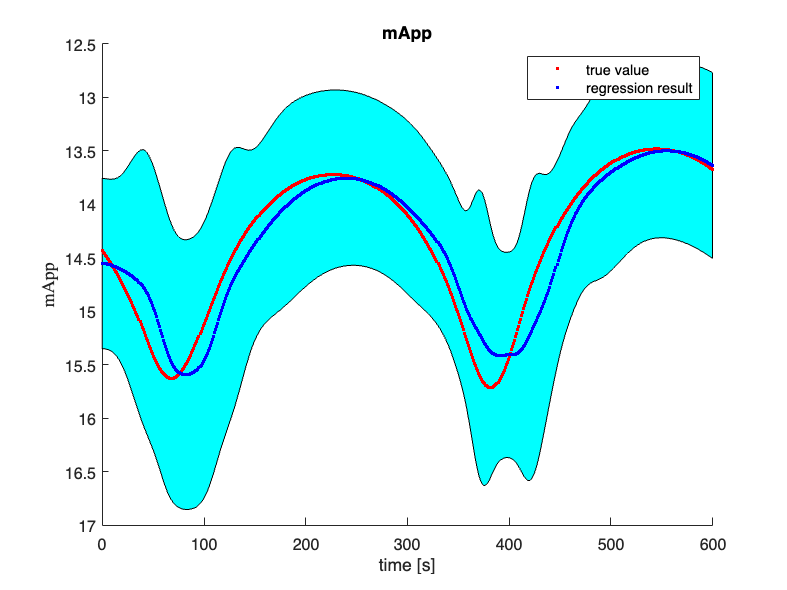

    if predictionStep == 1
        [t, x] = ode45(@(t, x)eomAttiOrb_h(t,x,const,earthVSOP,sat,jd), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,1:4) = x_ode(i+1,7:10); % [q]
        % x_reg(i+1,5:13) = x_reg(i,5:13); % [satPos, obsPos, sunPos]
        if strcmp(inputGP, "attitude, position, mApp_pastMean")

        % tstep_span後の位置情報が欲しい -----------
            x_reg(i+1,5:7) = x_ode(i+1,1:3) ./ r_valid_max; % [r]
    
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            x_reg(i+1,8:10) =  obsECI_tmp(end,:) ./ obsECI_valid_max; % [obsECI]
    
            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
            % x_reg(i+1,11:13) = sunPosI_tmp(end,:); % [sunPosI] % 一旦無視
        elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            
            x_reg(i+1, 5:7) = (x_ode(i+1, 1:3) - obsECI_tmp(end,:)) ./ obsToTarget_valid_max; % [r - obsECI]

            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
        elseif strcmp(inputGP, "attitude, mApp_pastMean")
        elseif strcmp(inputGP, "attitude")
        end
    
        x_reg(i+1, inputDim) = (x_reg(i, inputDim) * tSpanPast + valid.mApp(i+1,1)) / (tSpanPast+1); % [mApp_pastMean], 観測値を使う．

- predictionStep == 2. input: x_reg(i, :), output: y_reg_mu(i, 2:end)

    elseif predictionStep == 2
        for j = 2:1:size(y_reg_mu, 2)
            [y_reg_mu(i+1,j), y_reg_var(i+1,j)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train(:,j), params, Kinv_Dp); % input: 
        end
        y_reg_mu(i,2:end) = y_reg_mu(i,2:end) + y_train_mean(i,2:end);
        y_reg(i+1,2:5) = qMult_h(y_reg(i,2:5), rv2q(y_reg_mu(i,2:4)));
        y_reg(i+1,6:end) = y_reg(i,6:end) + y_reg_mu(i,5:end);
    end
end

- 最後にもう一回 observation step

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(x_reg(end, :), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
y_reg(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); 
% y_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

### plot

mkdir ../results/GP_static/
savedir = strcat(curdir, '/../results/GP_static/');

fignames = ["mApp"];
x_label = "time [s]";
y_labels = ["mApp"];

figure('Name', fignames(1));
plot_gpr(t_, y_reg(:,1), valid.mApp, y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);